## **Non-linear Model Trajectory with Circle Track**


$$\dot x(t)=u(t) \cos \theta(t) - v(t) \sin \theta(t)$$



$$\dot y(t)=u(t) \sin \theta(t) + v(t) \cos \theta(t)$$



$$u(t)=cte$$



$$\dot{v}(t) = -\frac{c_f + c_r}{M u} v(t) + \frac{c_r c - c_f b - M u^2}{M u} r(t) + \frac{c_f}{M} \delta(t)$$



$$\dot{r}(t) = \frac{c c_r - b c_f}{u I} v(t) - \frac{c^2 c_r + b^2 c_f}{u I} r(t) + \frac{c_f b}{I} \delta(t)$$


theta dot = r 

First approach without track limits

$x(0) = 0m$ ; $x(t_f)=3000 m$

$y(0) = 0m$ ; $y(t_f) = 1000m$

$\theta(0) = 0\degree$ ; $\theta(t_f)=50\degree$

Second Approach with circular Track

x= Radius * cos(theta-pi/2); 

y= Radius * sin(theta-pi/2);

% Define the parameters for the vehicle dynamics
c_f = 70000; % Front tire cornering stiffness
c_r = 50000; % Rear tire cornering stiffness
M = 1500;   % Mass of the vehicle in kg
I = 3000;   % Moment of inertia
b = 1.5;    % Distance from the center of gravity to the front axle
c = 1.5;    % Distance from the center of gravity to the rear axle

%initial and final conditions
ui= 1;
uf= 1;
thetai= deg2rad(0);
thetaf= deg2rad(90);
vi=0;
ri=0;
width = 25;
Radius = 100;
xi= Radius * cos(thetai-pi/2); %Start inside Track (circle)
xf= Radius * cos(thetaf-pi/2); %Finish inside Track
yi= Radius * sin(thetai-pi/2);
yf= Radius * sin(thetaf-pi/2);


% longitudinal velocity
%u = 100/3.6; %km/h to m/s

%Time step size
T = 1;

%Number of steps (initial guess)
N_min = 100;      % Theoretical minimum steps
N_max = 300;    % Theoretical maximum (Safe upper limit)
N = round((N_min + N_max) / 2); % Start in the middle

counter = 0;
max_iterations = 15;


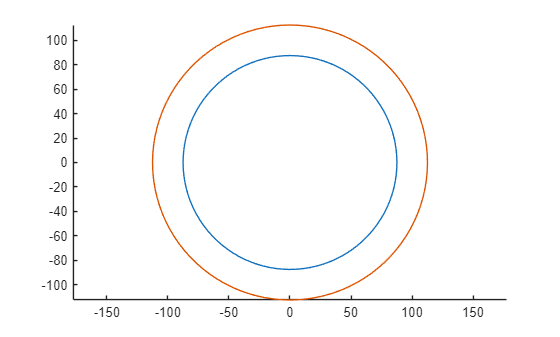

%Define Track (circle)
xc = 0;
yc = 0;
th = 0:pi/50:2*pi;
xinternal = (Radius-width/2) * cos(th) + xc;
xexternal = (Radius+width/2) * cos(th) + xc;
yinternal = (Radius-width/2) * sin(th) + yc;
yexternal = (Radius+width/2) * sin(th) + yc;
figure
hold on
axis equal
plot(xinternal, yinternal,xexternal,yexternal) 

% % Define Track Limits
% F_track = -sqrt(xc.^2 + yc.^2) + (Radius + width/2);
% %Define Function for TrackLimits ,
% % positive outside the track
% % negative inside the track 
% % zero on the track boundary
% d = sqrt(xc^2+yc^2);
% F_f = (d-(Radius-width/2))*(d-(Radius+width/2));

%Optimization options
%options = sdpsettings('solver','ipopt','verbose',0);
options = sdpsettings('solver', 'ipopt', 'verbose',0);
%('usex0',x_last,'usey0',y_last,'usev0',v_last,'useu0',u_last,'usetheta0',theta_last,'usedelta0',delta_last,'user0',r_last);

% 2. Manually append the specific IPOPT tolerances to the structure
% This tells IPOPT: "If the constraints are violated by less than 0.0001, count it as a success."
options.ipopt.constr_viol_tol = 1e-4;
options.ipopt.tol = 1e-4;              
options.ipopt.acceptable_tol = 1e-3;   % Even looser fallback tolerance
options.ipopt.max_iter = 1000;

% 3. Prevent the "Restoration Phase" crash by accepting "acceptable" points
%options.ipopt.accept_every_trial_step = 'yes';

%loop
while (N_max - N_min) > 1 && counter < max_iterations
    
    fprintf('Testing N = %d... ', N);
    %yalmip('clear');

    %Unknowns
    x = sdpvar(N,1);
    y = sdpvar(N,1);
    theta = sdpvar(N,1);
    v = sdpvar(N,1);
    r = sdpvar(N,1);
    delta = sdpvar(N,1);
    u = sdpvar(N,1); %velocity as unknown
    
    
    %Initial and final conditions
    F = [u(1) == ui, u(N) == uf, ...
         x(1) == xi, x(N) == xf,...
         y(1) == yi, y(N) == yf, ...
         theta(1) == thetai, theta(N) == thetaf,...
         v(1) == vi, r(1) == ri, ...
         abs(delta) <= deg2rad(40)];
    
    % Objective func
    obj = sum(delta.^2);  % sum of the squares of delta or V 
    
    %Problem conditions loop
    
    for k = 1:N-1
        F = [F x(k+1) == x(k) + T*(u(k)*cos(theta(k)) - v(k)*sin(theta(k)))];
        F = [F y(k+1) == y(k) + T*(u(k)*sin(theta(k)) + v(k)*cos(theta(k)))];
        F = [F v(k+1) == v(k) + T*(-(c_f + c_r)/(M*u(k)) * v(k) + (c_r*c - c_f*b - M*u(k)^2)/(M*u(k))...
            * r(k) + c_f/M * delta(k))];
        F = [F abs(v(k+1)) <= 1];
        F = [F r(k+1) == r(k) + T*((c*c_r - b*c_f)/(u(k)*I) * v(k) - (c^2*c_r + b^2*c_f)/(u(k)*I) * r(k)...
            + (c_f*b)/I * delta(k))];
        F = [F theta(k+1) == theta(k)+T*r(k)];
        F = [F u(k+1) <= 40];
        F = [F u(k+1) >= 1];
        %d = x(k)^2+y(k)^2; %car position
        F = [F (x(k)^2+y(k)^2)<=(Radius+width/2)^2];
        F = [F (Radius-width/2)^2<=(x(k)^2+y(k)^2)]; %TrackLimits - stay inside

    end
    
    optimization = optimize(F,obj,options);
    if optimization.problem == 0 %|| optimization.problem == 4 
        N_max = N;
        N = floor((N_min + N_max) / 2);
        fprintf('Feasible run\n')
        %saving the last solution to warm-start the new loops 
        x_last = double(x);
        y_last = double(y);
        v_last = double(v);
        theta_last = double(theta);
        u_last = double(u);
        delta_last = double(delta);
        r_last = double(r);
    else
        N_min = N;
        N = ceil((N_min + N_max) / 2);
        fprintf('Unfeasible run\n')
    end
    counter = counter + 1;
end

Testing N = 200... 


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************



fprintf('Optimal N found: %d\n', N_max);

N = N_max;
fprintf('Running Final Optimization with N = %d to generate trajectory...\n', N);

figure 
hold on
axis equal
grid on;
xlabel('X Position (m)');
ylabel('Y Position (m)'); 
title('Vehicle Trajectory');
plot(xinternal, yinternal,xexternal,yexternal,x_last,y_last)

figure
hold on
%axis equal
grid on
title('The lateral velocity of the car (V)')
plot(v_last*100/3.6)

figure
hold on
%axis equal
grid on
title('angle of the car (theta)')
plot(rad2deg(theta_last))

figure
hold on
%axis equal
grid on
title('Longitudinal velocity of the car(u)')
plot(u_last)

figure
hold on
grid on
title('steering angle(delta)')
plot(delta_last)